Call the ROC script

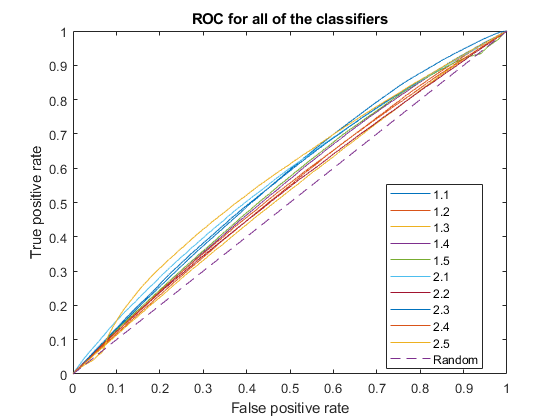

AUC11 = 0.5668

AUC12 = 0.5356

AUC13 = 0.5254

AUC14 = 0.5469

AUC15 = 0.5493

AUC21 = 0.5694

AUC22 = 0.5315

AUC23 = 0.5619

AUC24 = 0.5383

AUC25 = 0.5778

roc_v8_first_op

psame = 0.1360;
N = 6*31;
k = 0:N;

Idea : Choose classifier that has the greatest accuracy in our experiment

falsePosCell = {X11 X12 X13 X14 X15 X21 X22 X23 X24 X25};
truePosCell = {Y11 Y12 Y13 Y14 Y15 Y21 Y22 Y23 Y24 Y25};
thresholdCell = {T11 T12 T13 T14 T15 T21 T22 T23 T24 T25};
selectedPoints = zeros(length(falsePosCell),7); %th_distinguisher, th_bino, accuracy, fpr_bino, tpr_bino, fpr_dist, tpr_dist

%Get the best point for each one of them
for i = 1 : length(falsePosCell)
    fprVector = cell2mat(falsePosCell(i));
    tprVector = cell2mat(truePosCell(i));
    thresholdVector = cell2mat(thresholdCell(i));
    [selectedPoints(i,1), selectedPoints(i,2), selectedPoints(i,3), selectedPoints(i,4), selectedPoints(i,5), selectedPoints(i,6), selectedPoints(i,7)] = getThresholdDistinguisher(fprVector,tprVector,thresholdVector,psame,N);
end
clearvars falsePosCell truePosCell thresholdCell fprVector tprVector thresholdVector

Display thresholds for each classifier, their accuracy and total values for false positive rate and true positive rate

for i = 1 : size(selectedPoints,1)
    fprintf("Classifier %d",i);
    selectedPoints(i,1)
    selectedPoints(i,2)
    selectedPoints(i,3)
    selectedPoints(i,4)
    selectedPoints(i,5)
    selectedPoints(i,6)
    selectedPoints(i,7)
end

Classifier 1

ans = 0.9754

ans = 150

ans = 0.9054

ans = 0.0970

ans = 0.9054

ans = 0.7517

ans = 0.8399

Classifier 2

ans = 0.9732

ans = 148

ans = 0.7441

ans = 0.2725

ans = 0.7441

ans = 0.7680

ans = 0.8130

Classifier 3

ans = 0.9962

ans = 83

ans = 0.6699

ans = 0.3330

ans = 0.6699

ans = 0.4230

ans = 0.4600

Classifier 4

ans = 0.9881

ans = 129

ans = 0.8095

ans = 0.1921

ans = 0.8095

ans = 0.6512

ans = 0.7198

Classifier 5

ans = 0.9919

ans = 125

ans = 0.8305

ans = 0.1610

ans = 0.8305

ans = 0.6240

ans = 0.7003

Classifier 6

ans = 0.0256

ans = 80

ans = 0.8910

ans = 0.1095

ans = 0.8910

ans = 0.3695

ans = 0.4726

Classifier 7

ans = 0.0012

ans = 60

ans = 0.7165

ans = 0.2749

ans = 0.7165

ans = 0.2939

ans = 0.3391

Classifier 8

ans = 4.6143e-04

ans = 111

ans = 0.8661

ans = 0.1270

ans = 0.8661

ans = 0.5400

ans = 0.6322

Classifier 9

ans = 8.9702e-04

ans = 94

ans = 0.7554

ans = 0.2562

ans = 0.7554

ans = 0.4707

ans = 0.5294

Classifier 10

ans = 1.7327e-06

ans = 67

ans = 0.9336

ans = 0.0659

ans = 0.9336

ans = 0.2897

ans = 0.4114

Which is the best classifier

[val,ind] = max(selectedPoints(:,3))

val = 0.9336

ind = 10

Plot binomial distributions for that classifier

ytrue = binopdf(k,N,selectedPoints(ind,7));
prandom = psame * selectedPoints(ind,7) + (1 - psame) * selectedPoints(ind,6)

prandom = 0.3062

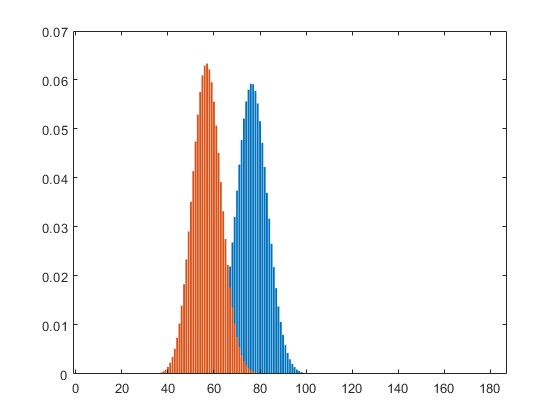

yrandom = binopdf(k,N,prandom);
bar(k,ytrue)
hold on
bar(k,yrandom)
hold off

Which gives us, according to Hanley's explanation

bitErrors = 521*(1-selectedPoints(ind,3))

bitErrors = 34.6141

cost = 0;
n2 = ceil(521/2);
for i = 1 : ceil(bitErrors/2)
    cost = cost + nchoosek(n2,i);
end

cost = cost * 521

cost = 1.5229e+30

Which is equivalent to 2^ to the 

exponent = log2(double(cost))

exponent = 100.2647

Save results

save('./results_characterization/v8_first_op.mat','selectedPoints');